# iTEBD: Ground state search

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

In this tutorial, we implement the **infinite time-evolving block decimation (iTEBD)** method, especially the original iTEBD algorithm proposed by G. Vidal [[G. Vidal, Phys. Rev. Lett. **98**, 070201 (2007)](https://journals.aps.org/prl/abstract/10.1103/PhysRevLett.98.070201)]. With this, we obtain the ground states of infinite-length spin chains, in Vidal's $\Gamma$-$\Lambda$ representation of ininite MPS. Note that the revised version by M. Hastings [[M. Hastings, J. Math. Phys. **50**, 095207 (2009)](https://aip.scitation.org/doi/abs/10.1063/1.3149556)] will be considered in the next tutorial.

The iTEBD obtains a ground state by applying many imaginary-time evolution steps to an infinite MPS in the $\Gamma$-$\Lambda$ notation. On the other hand, in previous tutorials on the DMRG, we variationally updated tensors of an finite-length MPS in canonical forms.

## Exercise (a): Complete the function for Vidal's original iTEBD

There is a function `iTEBD_GS_Vidal_Ex.m`, which is in the same sub-directory with this script. It is incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

## AKLT model

Check whether your implementation of `iTEBD_GS_Vidal_Ex.m` is correct, by applying it to the exactly solvable model. The simplest example is the AKLT model, which is the chain of spin-1's that interact via nearest-neighbor interactions,


$$\hat{H} = \sum_\ell \left[ (\hat{\vec{S}}_\ell \cdot \hat\vec{S}_{\ell+1}) + \frac{1}{3} (\hat\vec{S}_\ell \cdot \hat\vec{S}_{\ell+1})^2 \right].$$


clear

% iTEBD parameters
Nkeep = 10;
tau_ini = 1; % initial imaginary time step size
tau_fin = 0.01; % final imaginary time step size
Nstep = 200; % number of imaginary time steps
taus = tau_ini*((tau_fin/tau_ini).^linspace(0,1,Nstep));
% discrete imaginary time steps; decays slowly but exponentially

% Local operators
[S,I] = getLocalSpace('Spin',1);

Construct the interaction term for the AKLT Hamiltonian. Note that the second spin operator, $\hat\vec{S}_{\ell+1}$ in the construction of $\hat\vec{S}_\ell \cdot \hat\vec{S}_{\ell+1}$, should be Hermitian conjugated (i.e., complex conjugated and transposed).

% Heisenberg interaction as two-site gate S*S'
HSS = contract(S,3,3,permute(conj(S),[2 1 3]),3,3);
% (S*S')^2 interaction
HSS2 = contract(HSS,4,[2 4],HSS,4,[1 3],[1 3 2 4]);
%      2      4
%      ^      ^
%      |      |
%   [ HSS or HSS2 ]
%      |      |
%      ^      ^
%      1      3

% % % AKLT
H = HSS + HSS2/3;

As the interaction term acts on two sites, we consider a unit cell of two sites. Initialize the tensors with random elements. The conditions to be fulfilled as the ket tensor, such as the left- or right-normalization, are not satisfied by now; they will be automatically (and approximately) achieved by applying imaginary time evolutions.

% Initialize with random Lambda and Gamma
Lambda = cell(1,2);
Gamma = cell(1,2);
for itn = (1:numel(Lambda))
    Lambda{itn} = rand(Nkeep,1);
    Gamma{itn} = rand(Nkeep,Nkeep,size(I,2));
end

For convenience, we will call the bond associated with `Lambda{1}` as odd, and the other with `Lambda{2}` as even; The third leg of `Gamma{1}` acts on a physical space of an odd site, and that of `Gamma{2}` an even site. The odd (even) Hamiltonian is the sum of the interactions acting on $\ell$ and $\ell+1$ over all odd (even) $\ell$'s.

Run an iTEBD calculation. If `iTEBD_GS_Vidal_Ex.m` is implemented correctly, it would run like:

% iTEBD ground state search
[Lambda,Gamma,Eiter] = iTEBD_GS_Vidal_Ex(Lambda,Gamma,H,Nkeep,taus);

22-10-01 18:51:28 | iTEBD ground state search: Bond dim. Nkeep = 10, # of imag. time steps = 200
22-10-01 18:51:29 | #200/200, E = -0.66666667
Elapsed time: 0.3794s, CPU time: 0.53s, Avg # of cores: 1.397
22-10-01 18:51:29 | Memory usage : 3.12GiB


As we studied in previous lectures and tutorials, the ground state of the AKLT model is literally the AKLT state. We will compare the iTEBD result with the exact results.

First, let's compare the energy. The AKLT state has the energy per site (or equivalently the energy per bond) -2/3. The iTEBD result `Eiter(:,:,1)` is the energy per odd bond and `Eiter(:,:,2)` is that per even bond. The first direction of `Eiter` corresponds to the time steps specified by `taus` and the second index `1` (`2`) is for the time evolution by the odd (even) Hamiltonian.

We observe that both the energy per odd bond and the energy per even bond converge to the exact value with oscillations. 

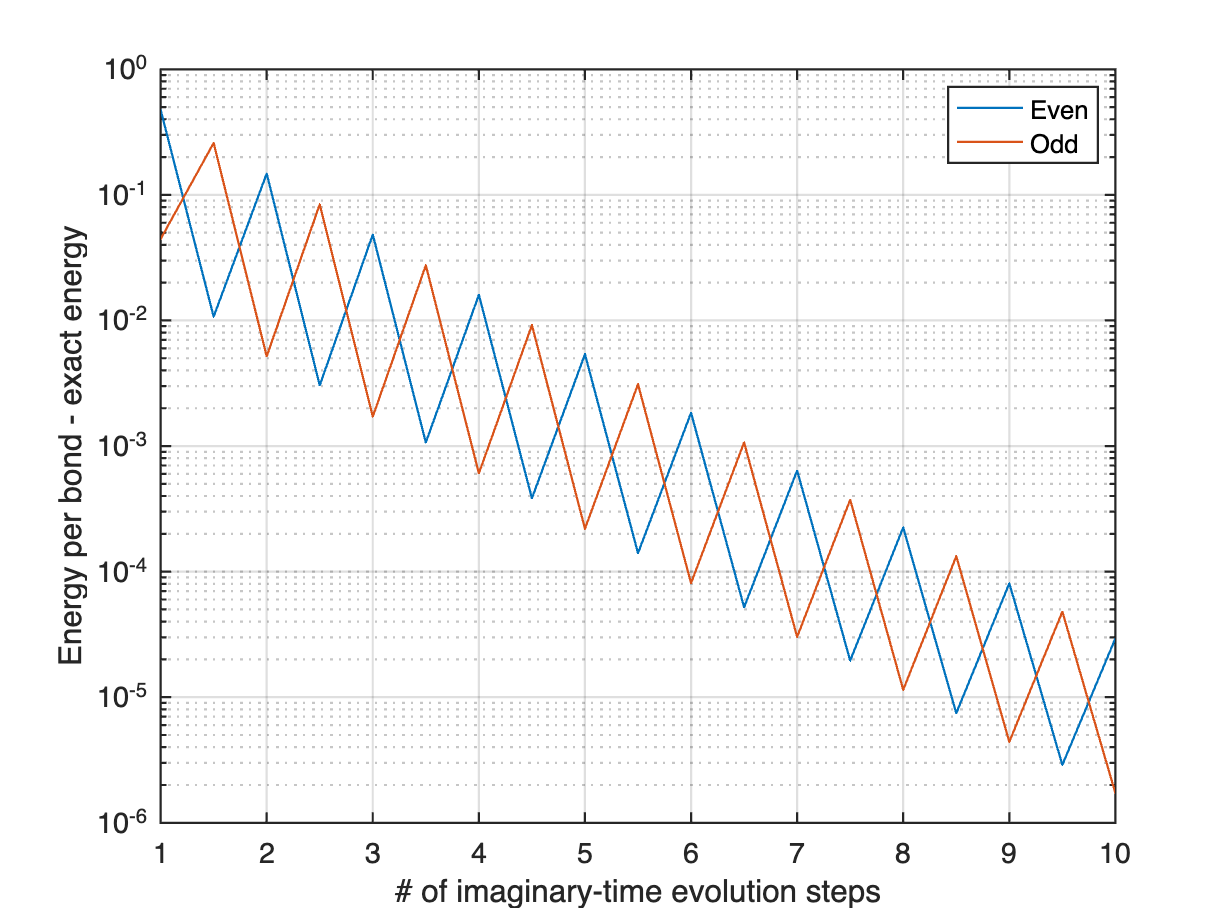

Eexact = -2/3;
% reshape Eiter for convenient plot
Eiter2 = reshape(permute(Eiter,[2 1 3]), ...
    [size(Eiter,2)*size(Eiter,1) size(Eiter,3)]);
figure;
plot((1:size(Eiter2,1)).'/2,Eiter2-Eexact,'LineWidth',1);
xlim([1 10]);
set(gca,'LineWidth',1,'FontSize',13,'YScale','log');
xlabel('# of imaginary-time evolution steps');
ylabel('Energy per bond - exact energy');
legend({'Even','Odd'});
grid on;

Note that we cut off the abscissa at the 10th step.

Why oscillating? When we update say, odd bonds, by applying the imaginary time evolutions to sites $\ell$ and $\ell+1$ with odd $\ell$, the time evolution operator changes the tensors in a way that the energy for the odd bond decreases at the cost of increasing the energy of the odd bond. 

To further see the convergence, we average the energy per even bond and that per odd bond. Note that the energy values (`E = ...`) shown in the log message of the function are the averaged energies as well. We plot the error of the averaged energy per bond in log scale.

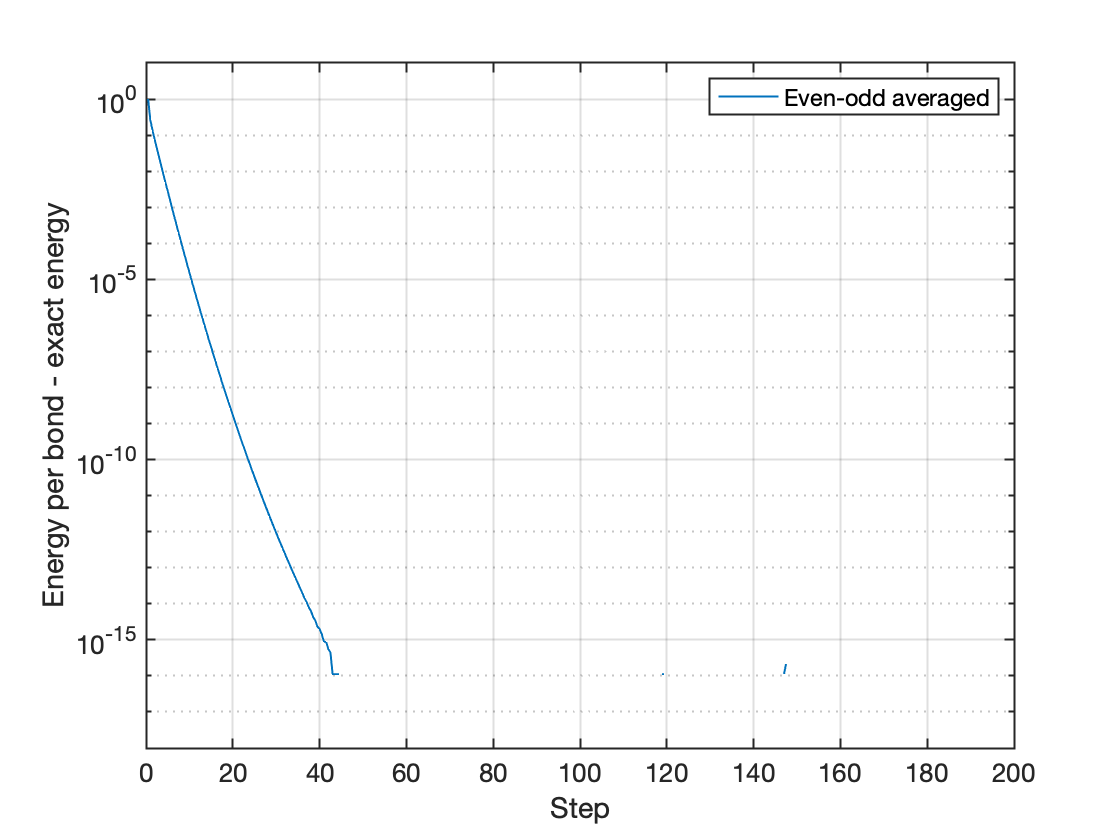

figure;
plot((1:size(Eiter2,1)).'/2,mean(Eiter2,2)-Eexact,'LineWidth',1);
ylim([1e-18 10]);
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
xlabel('Step');
ylabel('Energy per bond - exact energy');
legend({'Even-odd averaged'});
grid on;

The energy per site well converges to the exact value -2/3, up to double precision $\sim 10^{-16}$!

Then let's compare the tensors. Obtain a ket tensor for an odd site, by contracting Lambda`{2}` and `Gamma{1}`. This ket tensor is expected to be left-normalized.

A1 = contract(diag(Lambda{2}),2,2,Gamma{1},3,1);
disp(A1);


(:,:,1) =

   -0.5710   -0.3727
   -0.3761   -0.2455


(:,:,2) =

   -0.5295    0.2302
    0.2302    0.5295


(:,:,3) =

   -0.2455    0.3761
    0.3727   -0.5710



% check whether left-normalized
T = contract(conj(A1),3,[1 3],A1,3,[1 3]);
disp(T - eye(2));

   1.0e-15 *

    0.8882   -0.1527
   -0.1527         0



While the construction of the ket tensor `A1` is of `Lambda*Gamma` type, the tensor `A1` is also right-normalized. (In Vidal's convention, `Lambda*Gamma` is for left-normalized and `Gamma*Lambda` is for right-normalized.) It is, indeed, the non-trivial nature of the AKLT state.

% check whether right-normalized
T = contract(conj(A1),3,[2 3],A1,3,[2 3]);
disp(T - eye(2));

   1.0e-12 *

    0.4541   -0.0017
   -0.0017   -0.4531



It is also the case for the tensor for an even site.

% also for the tensor for another site
A2 = contract(diag(Lambda{1}),2,2,Gamma{2},3,1);
disp(A2);


(:,:,1) =

   -0.2455    0.3727
    0.3761   -0.5710


(:,:,2) =

    0.5295   -0.2302
   -0.2302   -0.5295


(:,:,3) =

   -0.5710   -0.3761
   -0.3727   -0.2455



% check whether left-normalized
T = contract(conj(A1),3,[1 3],A1,3,[1 3]);
disp(T - eye(2));

   1.0e-15 *

    0.8882   -0.1527
   -0.1527         0



% check whether right-normalized
T = contract(conj(A1),3,[2 3],A1,3,[2 3]);
disp(T - eye(2));

   1.0e-12 *

    0.4541   -0.0017
   -0.0017   -0.4531



There are only two finite singular values that are degenerate. They are the Schmidt coefficients of the valence bond state, i.e., the singlet of two spin-1/2 virtual particles.

% singular values
disp(Lambda{1}.' - 1/sqrt(2));

   1.0e-12 *

    0.2434   -0.2434



disp(Lambda{2}.' - 1/sqrt(2));

   1.0e-12 *

    0.2416   -0.2414



The iTEBD results `A1` and `A2` do not look the same as the bulk tensor defined for constructing the AKLT state analytically. First, `A1` and `A2` are not identical, since even-odd oscillation naturally comes from our consideration of a two-site unit cell. The differences among those tensors come from the arbitrary degrees of freedom associated with the unitary transformations on the bond space (i.e., the Hilbert space of the left and right legs), which is called gauge transformation.

Another way to analyze the tensor is to study the transfer operator. The eigenvalues of the transfer operator are independent from the gauge transformation on the bond space. Due to the even-odd oscillation, we will consider the transfer operator for the whole unit cell (i.e., two sites).

% contract Gamma*Lambda*Gamma*Lambda
T = contract(Gamma{1},3,2,diag(Lambda{1}),2,1,[1 3 2]);
T = contract(T,3,2,Gamma{2},3,1);
T = contract(T,4,3,diag(Lambda{2}),2,1);
% transfer operator
W = contract(conj(T),4,[2 3],T,4,[2 3],[1 3 2 4]);
% reshape W as matrix
MW = reshape(W,[size(W,1)*size(W,2) size(W,3)*size(W,4)]);
[VW,DW] = eig(MW);
[DW,ids] = sort(diag(DW),'descend');
VW = VW(:,ids);

(Note that `eig` function computes the eigenvectors `V` and eigenvalues `D` of matrix `M` such that `M*V = V*D`, i.e., the eigenvectors are acted onto the right side of `M`.) The eigenvalues of the transfer operator per one site can be obtained as the square roots of the eigenvalues for two sites.

% eigenvalue of transfer operator per *one site*
disp(sqrt(DW(:)).');

    1.0000    0.3333    0.3333    0.3333



The largest eigenvalue of the transfer operator per one site should be one, and the eigenvector associated with that eigenvalue should be proportional to the identity matrix, after reshaping.

% should be proportional to the identity if tensors are "orthogonal"
VM2 = reshape(VW(:,1),[size(W,1) size(W,2)]);
disp(VM2);

   -0.7071   -0.0000
   -0.0000   -0.7071



Why? This "eigenvector" means that the identity matrix (rank-2) acted onto the transfer operator (rank-4) on the right side is "transferred" to the identity matrix (rank-2) on the left side. It means nothing but the right-normalization of the tensor `Gamma*Lambda*Gamma*Lambda`.

The other eigenvalues, which are three degenerate 1/3's, are identical to what we have learnt from the previous exercise.

## Spin-1 Heisenberg model

Now let's move on to a more complicated example. Consider the spin-1 Heisenberg model,


$$\hat{H} = \sum_\ell \hat\vec{S}_\ell \cdot \hat\vec{S}_{\ell+1} .$$


This Hamiltonian looks much simpler than the AKLT model, but the ground state of the Heisenberg model is more involved than the AKLT state. Nevertheless, this model and the AKLT model both lie in the Haldane phase, which has a finite gap between the ground and first excited states in the thermodynamic limit. The Haldane phase is topologically nontrivial, as there is a symmetry-protected topological order.

We use the iTEBD to obtain the ground state and its energy. Here we set larger `Nkeep` and more `Nstep` than in the AKLT example. In accordance with larger `Nstep`, we also decrease the final imaginary time step size `beta_fin`.

clear

% iTEBD parameters
Nkeep = 30;
tau_ini = 1; % initial imaginary time step size
tau_fin = 1e-6; % final imaginary time step size
Nstep = 2e3; % number of imaginary time steps
taus = tau_ini*((tau_fin/tau_ini).^linspace(0,1,Nstep));
% discrete imaginary time steps; decays slowly but exponentially

% Local operators
[S,I] = getLocalSpace('Spin',1);

% Heisenberg interaction as two-site gate S*S'
H = contract(S,3,3,permute(conj(S),[2 1 3]),3,3);

% Initialize with random Lambda and Gamma
Lambda = cell(1,2);
Gamma = cell(1,2);
for itn = (1:numel(Lambda))
    Lambda{itn} = rand(Nkeep,1);
    Gamma{itn} = rand(Nkeep,Nkeep,size(I,2));
end

% iTEBD ground state search
[Lambda,Gamma,Eiter] = iTEBD_GS_Vidal_Ex(Lambda,Gamma,H,Nkeep,taus);

22-10-01 18:51:29 | iTEBD ground state search: Bond dim. Nkeep = 30, # of imag. time steps = 2000
22-10-01 18:51:32 | #500/2000, E = -1.3992815
22-10-01 18:51:35 | #1000/2000, E = -1.4014172
22-10-01 18:51:38 | #1500/2000, E = -1.4014805
22-10-01 18:51:40 | #2000/2000, E = -1.4014825
Elapsed time: 10.96s, CPU time: 112.2s, Avg # of cores: 10.24
22-10-01 18:51:40 | Memory usage : 3.14GiB


The ground-state energy of the spin-1 Heisenberg model is -1.401484039 [[S. R. White and D. A. Huse, Phys. Rev. B **48**, 3844 (1993)](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.48.3844)], obtained by using an infinite-system variant of DMRG. The energies per odd bond and per even bond converge to this "numerically exact" value, with oscillation.

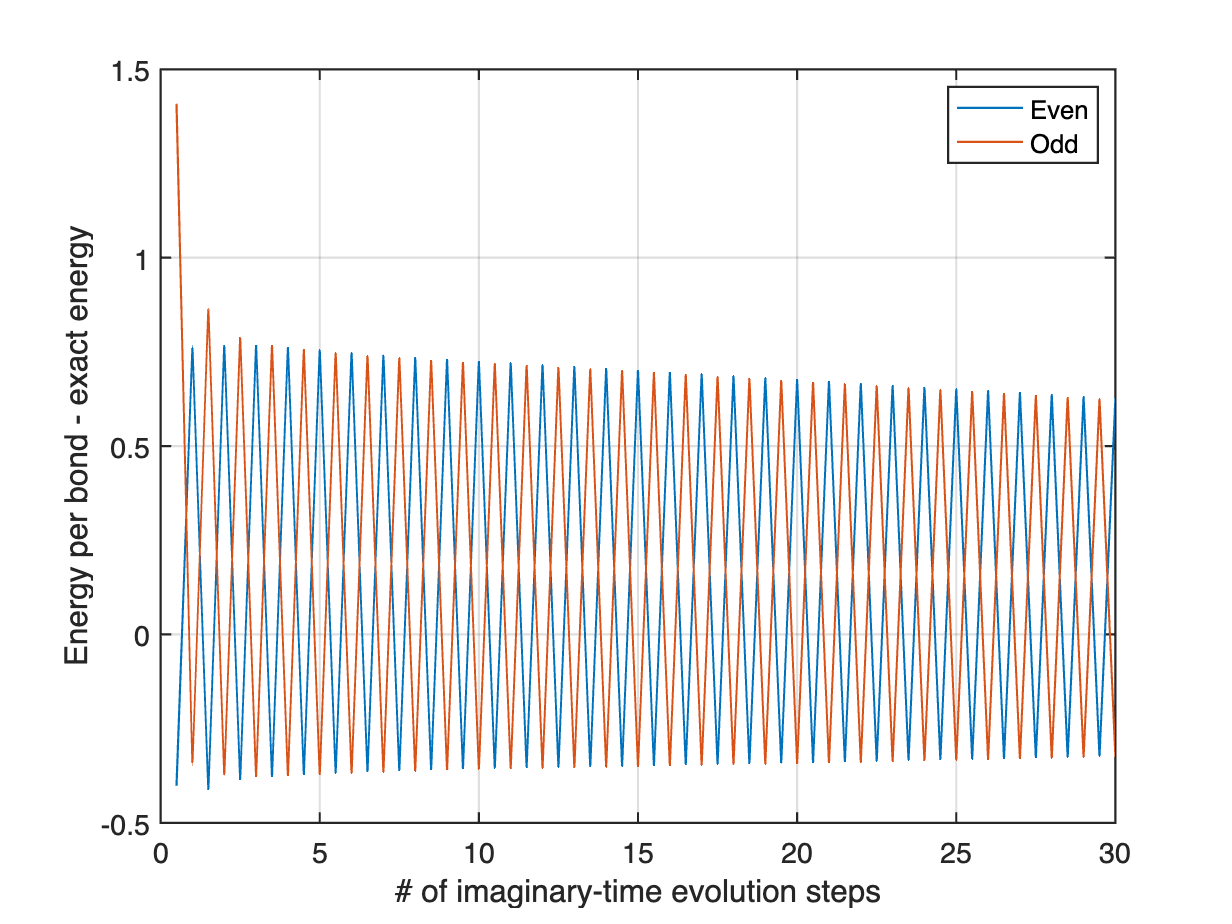

Eexact = -1.401484039;
% reshape Eiter for convenient plot
Eiter2 = reshape(permute(Eiter,[2 1 3]), ...
    [size(Eiter,2)*size(Eiter,1) size(Eiter,3)]);
figure;
plot((1:size(Eiter2,1)).'/2,Eiter2-Eexact,'LineWidth',1);
set(gca,'LineWidth',1,'FontSize',13,'YScale','linear');
xlim([0 30]);
xlabel('# of imaginary-time evolution steps');
ylabel('Energy per bond - exact energy');
legend({'Even','Odd'});
grid on;

And the averaged energy, i.e., the energy per site, converges to the exact value from above. With the current choice of parameters (`Nkeep`, `tau_ini`, `tau_fin`, and `Nstep`), the error at the last iteration is $\sim 10^{-6}$.

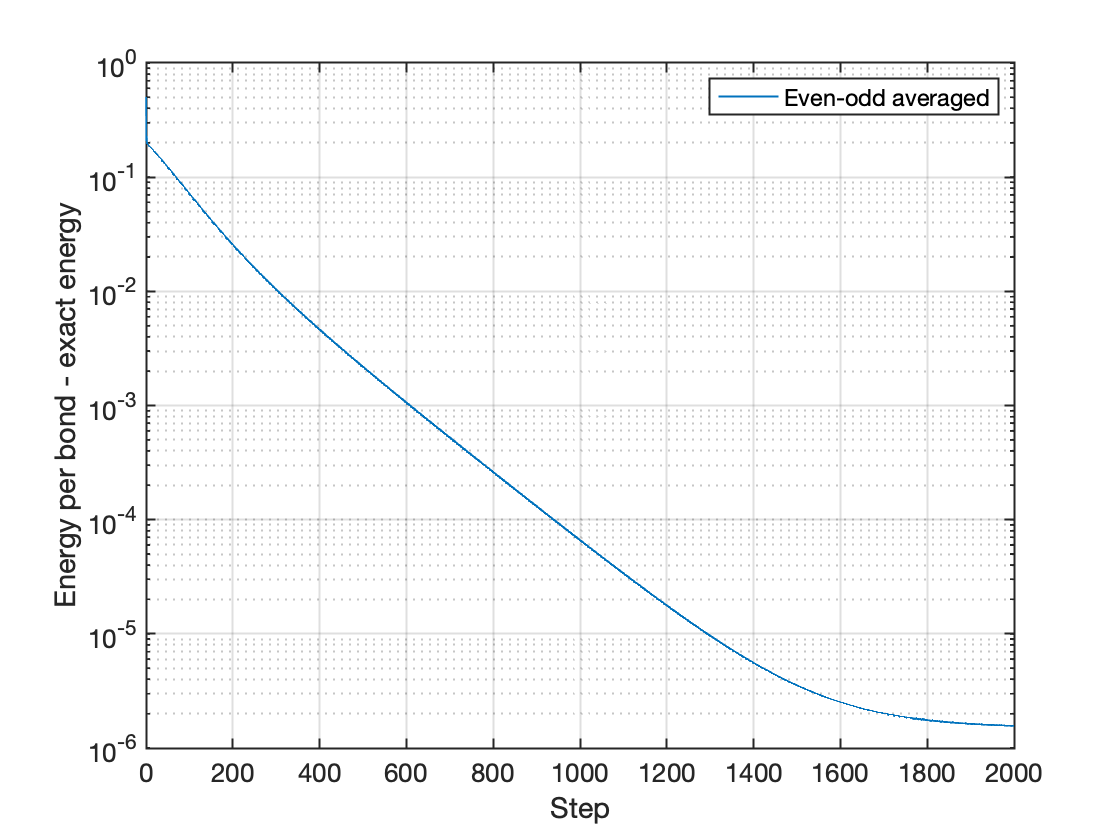

figure;
plot((1:size(Eiter2,1)).'/2,mean(Eiter2,2)-Eexact,'LineWidth',1);
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
xlabel('Step');
ylabel('Energy per bond - exact energy');
legend({'Even-odd averaged'});
grid on;

## Exercise (b): Check the energy convergence

By changing numerically parameters, we can achieve better convergence to the numerically exact value. Try changing (i) `tau_fin`, (ii) `Nstep`, or (iii) `Nkeep`.

The result singular values, stored in `Lambda{..}`, are decaying exponentially. The exponential decay corresponds to the nature of the system which is gapped. The logarithms of the singular values, called **entanglement spectrum**, have certain structure. We see that they have even degeneracies: 2, 4, 2, 4, 4, 6, and so on. Such even degeneracies are indicators of topological nature of the system. Refer to [[F. Pollmann, A. M. Turner, E. Berg, and M. Oshikawa, Phys. Rev. B **81**, 064439 (2010)](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.81.064439)].

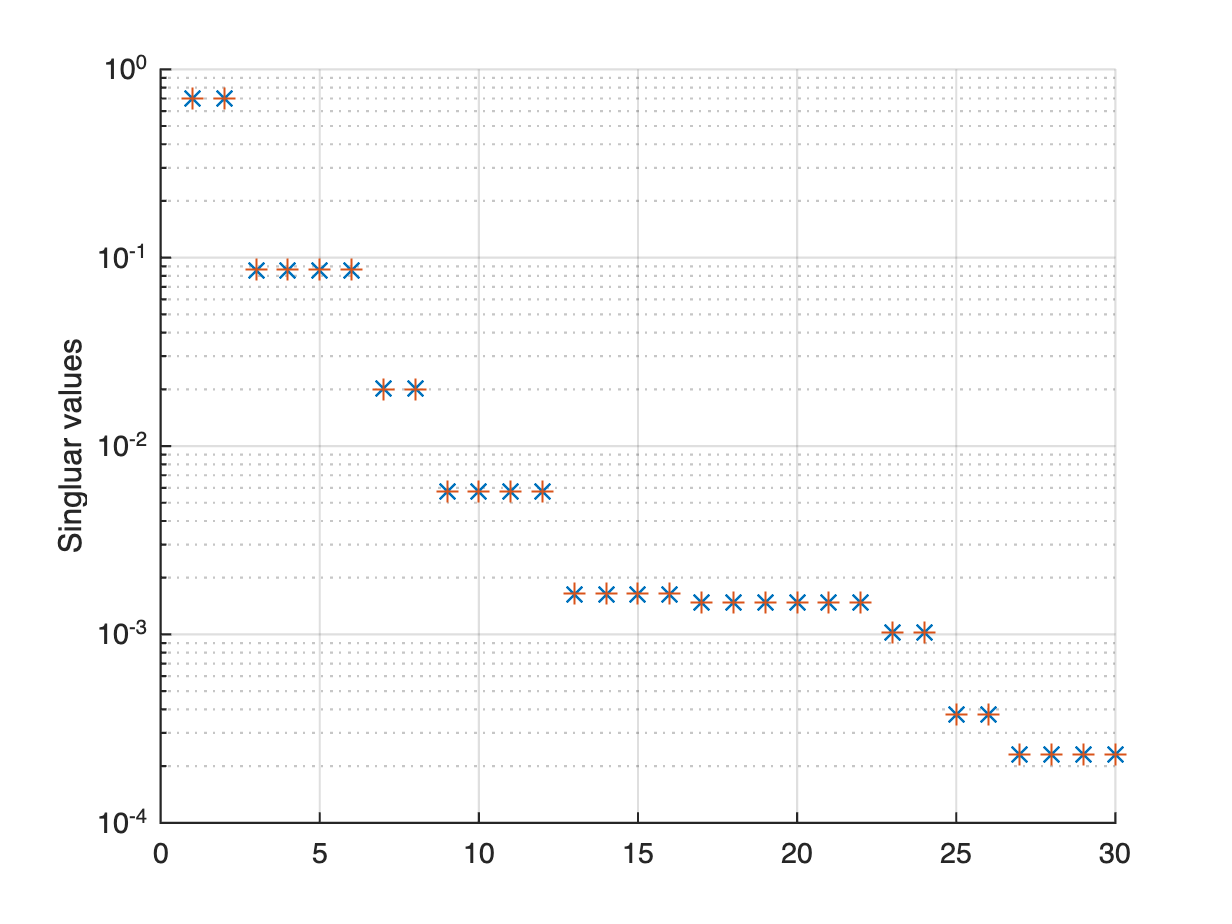

figure;
hold on;
plot(Lambda{1},'x','LineWidth',1,'MarkerSize',10);
plot(Lambda{2},'+','LineWidth',1,'MarkerSize',10);
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
ylabel('Singluar values');
grid on;

As mentioned above, the eigenvector of the transfer operator associated with the largest eigenvalue needs to be proportional to the identity matrix after reshaping, since it indicates the left- or right-normalization. How about this solution of the spin-1 Heisenberg chain?

% contract Gamma*Lambda*Gamma*Lambda
T = contract(Gamma{1},3,2,diag(Lambda{1}),2,1,[1 3 2]);
T = contract(T,3,2,Gamma{2},3,1);
T = contract(T,4,3,diag(Lambda{2}),2,1);
% transfer operator
W = contract(conj(T),4,[2 3],T,4,[2 3],[1 3 2 4]);
% reshape W as matrix
MW = reshape(W,[size(W,1)*size(W,2) size(W,3)*size(W,4)]);
[VW,DW] = eig(MW);
[DW,ids] = sort(diag(DW),'descend');
VW = VW(:,ids);
disp(DW(1));

    1.0000



% should be proportional to the identity if tensors are "orthogonal"
VM2 = reshape(VW(:,1),[size(W,1) size(W,2)]);
% as the matrix VM2 is large, so let's compare only the differences
% deviation from the identity matrix (up to overall prefactor)
VM2diff = abs(eye(size(VM2))*(trace(VM2)/size(VM2,1)) - VM2);
disp(mean(VM2diff(:))); % average error

   1.6558e-08



The eigenvector of the transfer operator associated with the largest eigenvalue ("dominant eigenvector" of the transfer operator) is proportional to the identity matrix up to numerical error $\sim 10^{-8}$.